# **SHORT PROJECT: FIRST DELIVERABLE**

Jose García Torres & Iván López Buira **[G11F]**

## DICOM INFORMATION

### Center and diameter of the tumor

C_T = [0.130 0.097 0.049 1]' % X Y Z (1)

C_T =     0.1300
    0.0970
    0.0490
    1.0000


.

D_T = 0.0330

### Containing Box and offset Coordinates

T_I_U = troty(pi) % Frame description I wrt U

T_I_U =     -1     0     0     0
     0     1     0     0
     0     0    -1     0
     0     0     0     1


T_CB_I = T_I_U * transl(0.041,0.026,0) % Frame description CB wrt I

T_CB_I =    -1.0000         0         0   -0.0410
         0    1.0000         0    0.0260
         0         0   -1.0000         0
         0         0         0    1.0000



v= [0.041 0.026 0 1;
    0.205 0.026 0 1;
    0.205 0.236 0 1;
    0.041 0.236 0 1;
    0.041 0.026 0.1568 1; 
    0.205 0.026 0.1568 1;
    0.205 0.236 0.1568 1;
    0.041 0.236 0.1568 1]  % Coordinates with repect to Image Reference Frame (T_I_U)

v =     0.0410    0.0260         0    1.0000
    0.2050    0.0260         0    1.0000
    0.2050    0.2360         0    1.0000
    0.0410    0.2360         0    1.0000
    0.0410    0.0260    0.1568    1.0000
    0.2050    0.0260    0.1568    1.0000
    0.2050    0.2360    0.1568    1.0000
    0.0410    0.2360    0.1568    1.0000


### Fiducial Coordinates

F1_I = [0.071 0.213 0.112 1]'

F1_I =     0.0710
    0.2130
    0.1120
    1.0000


F2_I = [0.186 0.209 0.0658 1]'

F2_I =     0.1860
    0.2090
    0.0658
    1.0000


F3_I = [0.122 0.062 0.0252 1]'

F3_I =     0.1220
    0.0620
    0.0252
    1.0000


## DISPLAY

### Reference frame {I} and {CB}

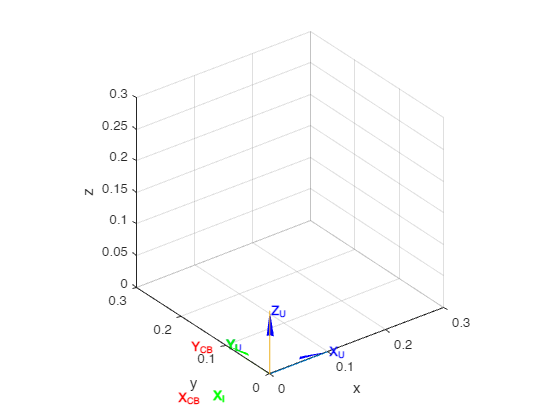

plotvol([0 0.3 0 0.3 0 0.3])

trplot(transl(0,0,0), 'frame', 'U', 'color', 'b','length',0.1 ,'width', 2,'arrow',...
        'text_opts',{'FontSize', 10, 'FontWeight', 'bold'} ) % {U}

trplot(T_I_U, 'frame', 'I', 'color', 'g','length',0.1 ,'width', 2,'arrow',...
        'text_opts',{'FontSize', 10, 'FontWeight', 'bold'} ) % {I}

trplot(T_CB_I, 'frame', 'CB', 'color', 'r','length',0.1 ,'width', 2,'arrow',...
        'text_opts',{'FontSize', 10, 'FontWeight', 'bold'} ) % {CB}

### **Skull Containing Box**

v_u = zeros(8,4)

v_u =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0



for f = 1:8
    v_u(f,(1:4)) = T_I_U * v(f, (1:4))'
end

v_u =    -0.0410    0.0260         0    1.0000
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


v_u =    -0.0410    0.0260         0    1.0000
   -0.2050    0.0260         0    1.0000
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


v_u =    -0.0410    0.0260         0    1.0000
   -0.2050    0.0260         0    1.0000
   -0.2050    0.2360         0    1.0000
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


v_u =    -0.0410    0.0260         0    1.0000
   -0.2050    0.0260         0    1.0000
   -0.2050    0.2360         0    1.0000
   -0.0410    0.2360         0    1.0000
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


v_u =    -0.0410    0.0260         0    1.0000
   -0.2050    0.0260         0    1.0000
   -0.2050    0.2360         0    1.0000
   -0.0410    0.2360         0    1.0000
   -0.0410    0.0260   -0.1568    1.0000
         0         0         0         0
         0         0         0         0
         0         0         0         0


v_u =    -0.0410    0.0260         0    1.0000
   -0.2050    0.0260         0    1.0000
   -0.2050    0.2360         0    1.0000
   -0.0410    0.2360         0    1.0000
   -0.0410    0.0260   -0.1568    1.0000
   -0.2050    0.0260   -0.1568    1.0000
         0         0         0         0
         0         0         0         0


v_u =    -0.0410    0.0260         0    1.0000
   -0.2050    0.0260         0    1.0000
   -0.2050    0.2360         0    1.0000
   -0.0410    0.2360         0    1.0000
   -0.0410    0.0260   -0.1568    1.0000
   -0.2050    0.0260   -0.1568    1.0000
   -0.2050    0.2360   -0.1568    1.0000
         0         0         0         0


v_u =    -0.0410    0.0260         0    1.0000
   -0.2050    0.0260         0    1.0000
   -0.2050    0.2360         0    1.0000
   -0.0410    0.2360         0    1.0000
   -0.0410    0.0260   -0.1568    1.0000
   -0.2050    0.0260   -0.1568    1.0000
   -0.2050    0.2360   -0.1568    1.0000
   -0.0410    0.2360   -0.1568    1.0000



v_u

v_u =    -0.0410    0.0260         0    1.0000
   -0.2050    0.0260         0    1.0000
   -0.2050    0.2360         0    1.0000
   -0.0410    0.2360         0    1.0000
   -0.0410    0.0260   -0.1568    1.0000
   -0.2050    0.0260   -0.1568    1.0000
   -0.2050    0.2360   -0.1568    1.0000
   -0.0410    0.2360   -0.1568    1.0000



f = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8]

f =      1     2     6     5
     2     3     7     6
     3     4     8     7
     4     1     5     8
     1     2     3     4
     5     6     7     8


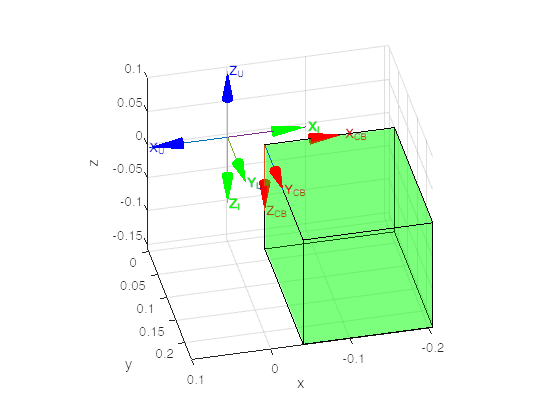

patch('Vertices',v_u(:, 1:3),'Faces',f,'FaceVertexCData',hsv(6),'FaceColor','g','FaceAlpha',0.3)
view(167, 35)
axis equal

### Tumor and Fiducials

`[Tumor]`

[X,Y,Z] = sphere;

r = D_T / 2

r = 0.0165


X2 = X * r

X2 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0026   -0.0025   -0.0021   -0.0015   -0.0008    0.0000    0.0008    0.0015    0.0021    0.0025    0.0026    0.0025    0.0021    0.0015    0.0008    0.0000   -0.0008   -0.0015   -0.0021   -0.0025   -0.0026
   -0.0051   -0.0048   -0.0041   -0.0030   -0.0016    0.0000    0.0016    0.0030    0.0041    0.0048    0.0051    0.0048    0.0041    0.0030    0.0016    0.0000   -0.0016   -0.0030   -0.0041   -0.0048   -0.0051
   -0.0075   -0.0071   -0.0061   -0.0044   -0.0023    0.0000    0.0023    0.0044    0.0061    0.0071    0.0075    0.0071    0.0061    0.0044    0.0023    0.0000   -0.0023   -0.0044   -0.0061   -0.0071   -0.0075
   -0.0097   -0.0092   -0.0078   -0.0057   -0.0030    0.0000    0.0030    0.0057    0.0078    0.0092    0.0097    0.0092    0.0078    0.0057    0.0030 

Y2 = Y * r

Y2 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -0.0008   -0.0015   -0.0021   -0.0025   -0.0026   -0.0025   -0.0021   -0.0015   -0.0008         0    0.0008    0.0015    0.0021    0.0025    0.0026    0.0025    0.0021    0.0015    0.0008         0
         0   -0.0016   -0.0030   -0.0041   -0.0048   -0.0051   -0.0048   -0.0041   -0.0030   -0.0016         0    0.0016    0.0030    0.0041    0.0048    0.0051    0.0048    0.0041    0.0030    0.0016         0
         0   -0.0023   -0.0044   -0.0061   -0.0071   -0.0075   -0.0071   -0.0061   -0.0044   -0.0023         0    0.0023    0.0044    0.0061    0.0071    0.0075    0.0071    0.0061    0.0044    0.0023         0
         0   -0.0030   -0.0057   -0.0078   -0.0092   -0.0097   -0.0092   -0.0078   -0.0057   -0.0030         0    0.0030    0.0057    0.0078    0.0092 

Z2 = Z * r

Z2 =    -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165
   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163
   -0.0157   -0.0157   -0.0157   -0.0157   -0.0157   -0.0157   -0.0157   -0.0157   -0.0157   -0.0157   -0.0157   -0.0157   -0.0157   -0.0157   -0.0157   -0.0157   -0.0157   -0.0157   -0.0157   -0.0157   -0.0157
   -0.0147   -0.0147   -0.0147   -0.0147   -0.0147   -0.0147   -0.0147   -0.0147   -0.0147   -0.0147   -0.0147   -0.0147   -0.0147   -0.0147   -0.0147   -0.0147   -0.0147   -0.0147   -0.0147   -0.0147   -0.0147
   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133 


C_T_U = T_I_U * C_T

C_T_U =    -0.1300
    0.0970
   -0.0490
    1.0000



surf(X2+C_T_U(1,1), Y2+C_T_U(2,1), Z2+C_T_U(3,1),'FaceColor',[1 0 0])
axis equal

`[Fiducials]`

r2 = 0.005

r2 = 0.0050


X3 = X * r2

X3 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0008   -0.0007   -0.0006   -0.0005   -0.0002    0.0000    0.0002    0.0005    0.0006    0.0007    0.0008    0.0007    0.0006    0.0005    0.0002    0.0000   -0.0002   -0.0005   -0.0006   -0.0007   -0.0008
   -0.0015   -0.0015   -0.0013   -0.0009   -0.0005    0.0000    0.0005    0.0009    0.0013    0.0015    0.0015    0.0015    0.0013    0.0009    0.0005    0.0000   -0.0005   -0.0009   -0.0013   -0.0015   -0.0015
   -0.0023   -0.0022   -0.0018   -0.0013   -0.0007    0.0000    0.0007    0.0013    0.0018    0.0022    0.0023    0.0022    0.0018    0.0013    0.0007    0.0000   -0.0007   -0.0013   -0.0018   -0.0022   -0.0023
   -0.0029   -0.0028   -0.0024   -0.0017   -0.0009    0.0000    0.0009    0.0017    0.0024    0.0028    0.0029    0.0028    0.0024    0.0017    0.0009 

Y3 = Y * r2

Y3 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -0.0002   -0.0005   -0.0006   -0.0007   -0.0008   -0.0007   -0.0006   -0.0005   -0.0002         0    0.0002    0.0005    0.0006    0.0007    0.0008    0.0007    0.0006    0.0005    0.0002         0
         0   -0.0005   -0.0009   -0.0013   -0.0015   -0.0015   -0.0015   -0.0013   -0.0009   -0.0005         0    0.0005    0.0009    0.0013    0.0015    0.0015    0.0015    0.0013    0.0009    0.0005         0
         0   -0.0007   -0.0013   -0.0018   -0.0022   -0.0023   -0.0022   -0.0018   -0.0013   -0.0007         0    0.0007    0.0013    0.0018    0.0022    0.0023    0.0022    0.0018    0.0013    0.0007         0
         0   -0.0009   -0.0017   -0.0024   -0.0028   -0.0029   -0.0028   -0.0024   -0.0017   -0.0009         0    0.0009    0.0017    0.0024    0.0028 

Z3 = Z * r2

Z3 =    -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050
   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049
   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048
   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045
   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040 


F1_U = T_I_U * F1_I

F1_U =    -0.0710
    0.2130
   -0.1120
    1.0000



surf(X3+F1_U(1,1),Y3+F1_U(2,1),Z3+F1_U(3,1),'FaceColor',[1 0 0])
axis equal

F2_U = T_I_U * F2_I

F2_U =    -0.1860
    0.2090
   -0.0658
    1.0000



surf(X3+F2_U(1,1),Y3+F2_U(2,1),Z3+F2_U(3,1),'FaceColor',[1 0 0])
axis equal


F3_U = T_I_U * F3_I

F3_U =    -0.1220
    0.0620
   -0.0252
    1.0000


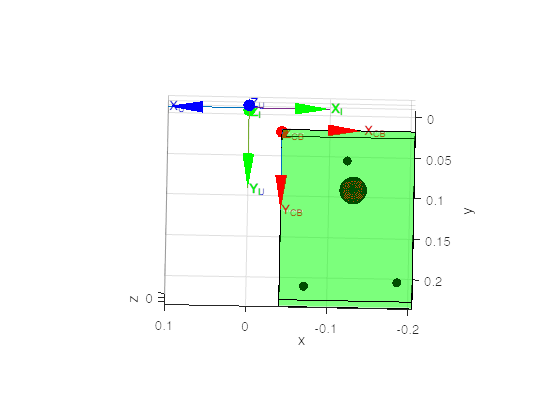


surf(X3+F3_U(1,1),Y3+F3_U(2,1),Z3+F3_U(3,1),'FaceColor',[1 0 0])
axis equal